%тест1
n_1 = 4;
A = [[40 9 0 0];
    [10 50 0 -4];
    [-9 4 64 0];
    [0 -14 7 80]];
b_1 = [24,-5,14,29]';
epsilon_1 = 1e-10;
x_1_si = SimpleIteration(A,b_1,epsilon_1);

Количество итераций:
    18



x_1_s = Seidel(A,b_1,epsilon_1);

Количество итераций: 
    10



x_1_si

x_1_si =    0.646209216812716
  -0.205374296969437
   0.322459064671967
   0.298344329877052


x_1_s

x_1_s =    0.646209216819929
  -0.205374296974416
   0.322459064676203
   0.298344329870309


%тест2
n_2 = 13;
H = hilb(n_2);
e = ones(n_2, 1);
b_2 = H*e;
epsilon_2 = 1e-11;
%x_2_si = SimpleIteration(H,b_2,epsilon_2);
x_2_s = Seidel(H,b_2,epsilon_2);

Количество итераций: 
    45551597



x_2_s

x_2_s =    0.999999905663248
   1.000004762105070
   0.999943028273011
   1.000262509150473
   0.999501608740206
   1.000219667720069
   1.000334830882771
   0.999934268899875
   0.999677052486747
   0.999829883809659


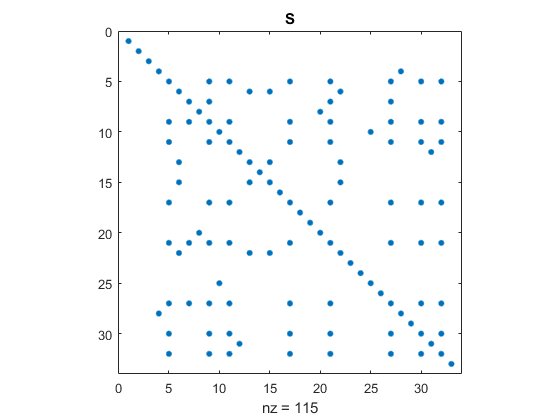

%тест3
n_3  = 33;
R = rand(n_3, 1, 'double');
S = sprandsym(n_3, 0.1, R);
spy(S), title('S');

epsilon_3 = 1e-11;
b_3 = ones(n_3, 1);
x_3_si = SimpleIteration(S, b_3, epsilon_3);

Количество итераций:
    75



x_3_s = Seidel(S, b_3, epsilon_3);

Количество итераций: 
    39



x_3_si

x_3_si =    1.227410000103284
   1.104006294457130
   7.874833224330065
   1.612603447587511
   0.281545395968383
  19.405795710967286
   1.371691828712879
   0.913153636373432
   0.830354874954887
   1.338685972347468


x_3_s

x_3_s =    1.227410000103284
   1.104006294457130
   7.874833224330065
   1.612603447587511
   0.281545395966863
  19.405795710967286
   1.371691828712855
   0.913153636373432
   0.830354874953910
   1.338685972347468
